# Mean Activity

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

## Part 0: Initialization

Specify the dataset to analyze

% We need to specify the prefix of the project we wish to analyze
Prefix = '2020-02-23-optoknirps_new_embryo6';

Variables depending on the data

- Start/Final frames

% WT: embryo6
start_frame = 40;
final_frame = 149;

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['/Users/jiaxi.zhao/Dropbox/OptoDropbox/#analysis/202004 - perturbation analysis/with_export/figure/' Prefix];

mkdir(FigPath)


% Specify the position of DynamicsResults folder
DynamicsResultsFolder = '/Users/jiaxi.zhao/Dropbox/OptoDropbox';

Now, load all the data

% Now we'll load the CompiledParticles dataset
% This generates a string that gives the path to CompiledParticles
LoadComNucleiPath = [DynamicsResultsFolder '/' Prefix '/CompiledNuclei.mat']; 

data.nuclei = load(LoadComNucleiPath);
%load(LoadNucleiPath)

ElapsedTime = data.nuclei.ElapsedTime-data.nuclei.ElapsedTime(start_frame);
Time = ElapsedTime(start_frame:final_frame);
APbinID = data.nuclei.APbinID;

## Draw figures for nuclei

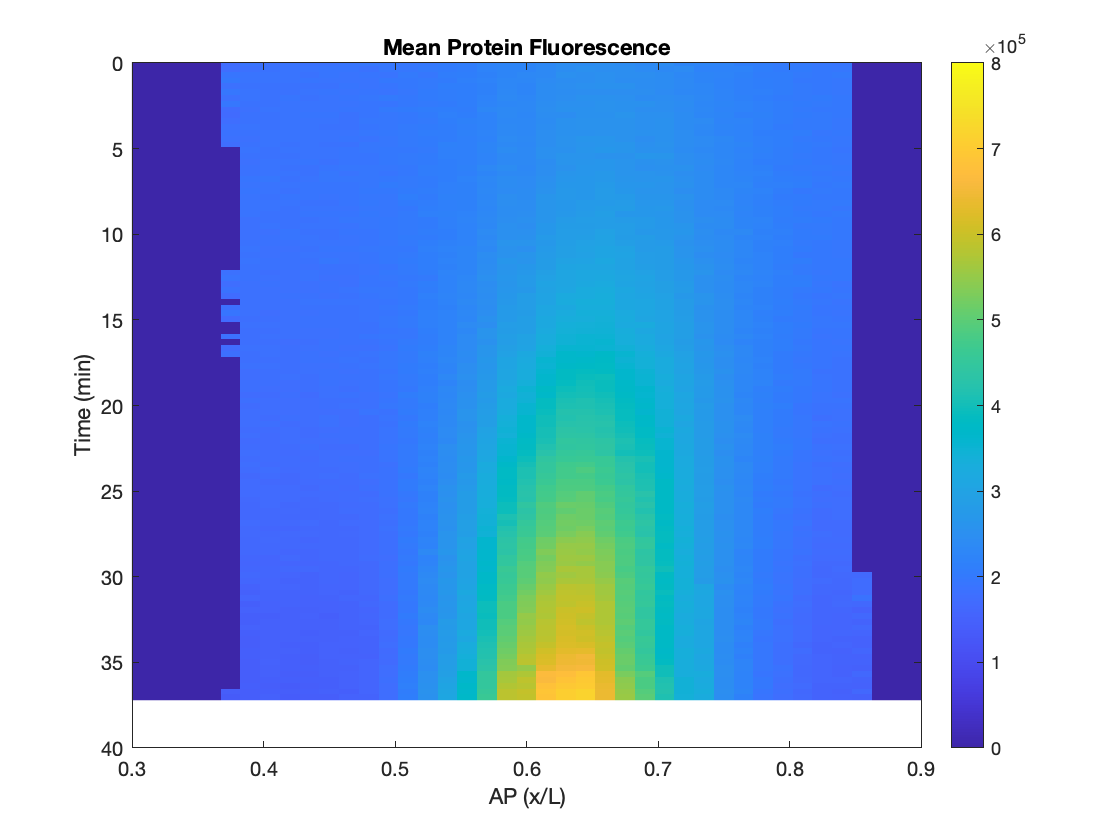

data_plot = data.nuclei.MeanVectorAP;

MeanNucleiFig = figure;
imagesc(APbinID,Time,data_plot(start_frame:final_frame,:));
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([0.3 0.9])
ylim([0 40])
colorbar
caxis([0 8E5])
title('Mean Protein Fluorescence')
saveas(MeanNucleiFig,[FigPath '/MeanProtein_fluo.pdf' ]);

## Plot them both together

Plot for bin 40-...

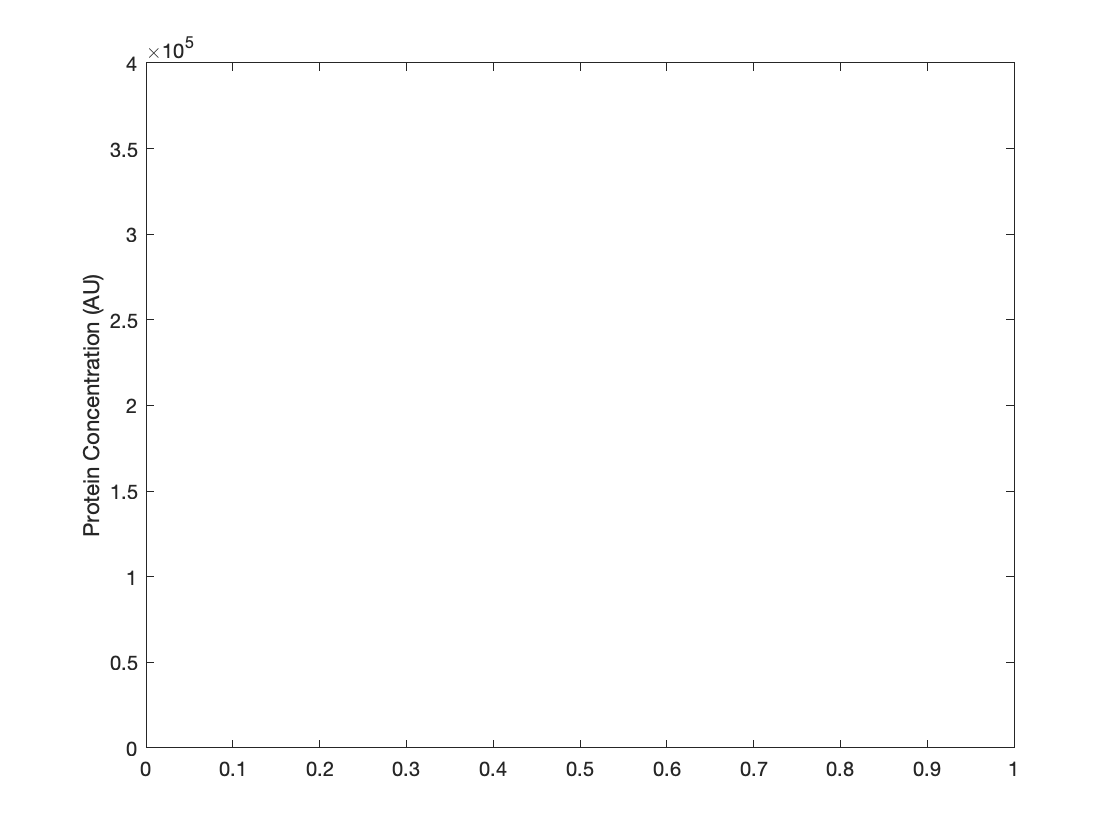

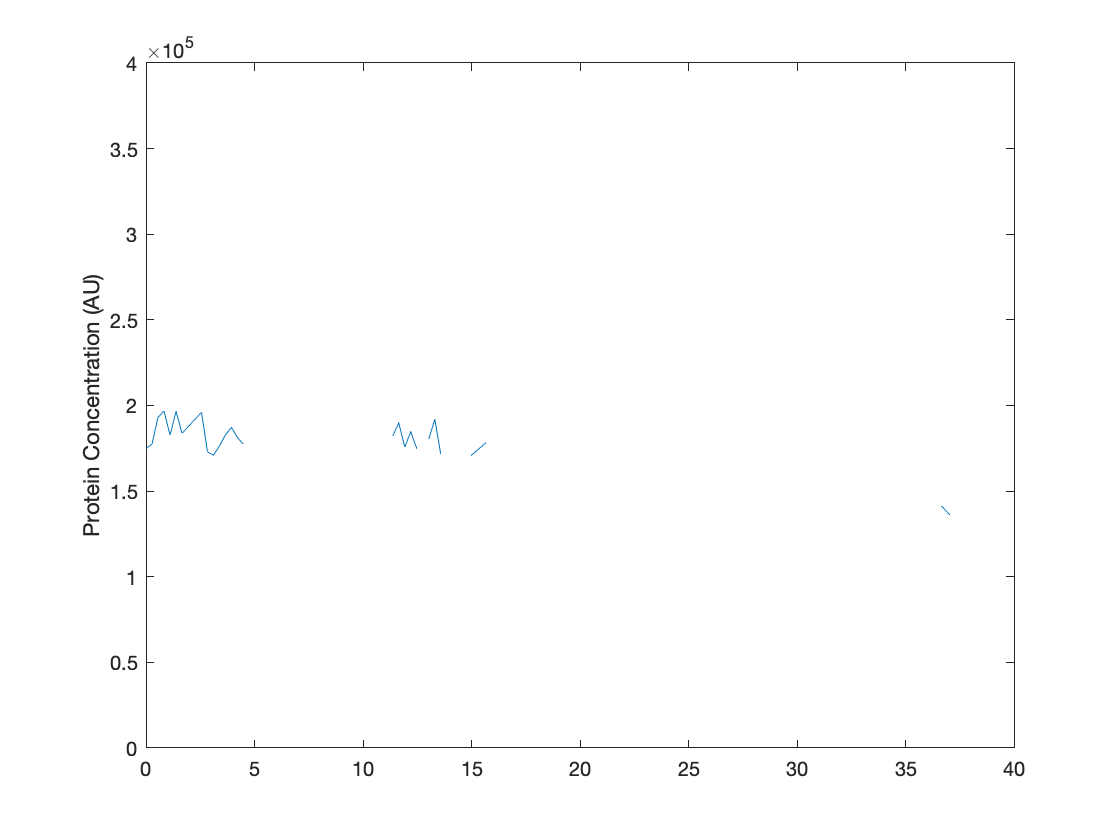

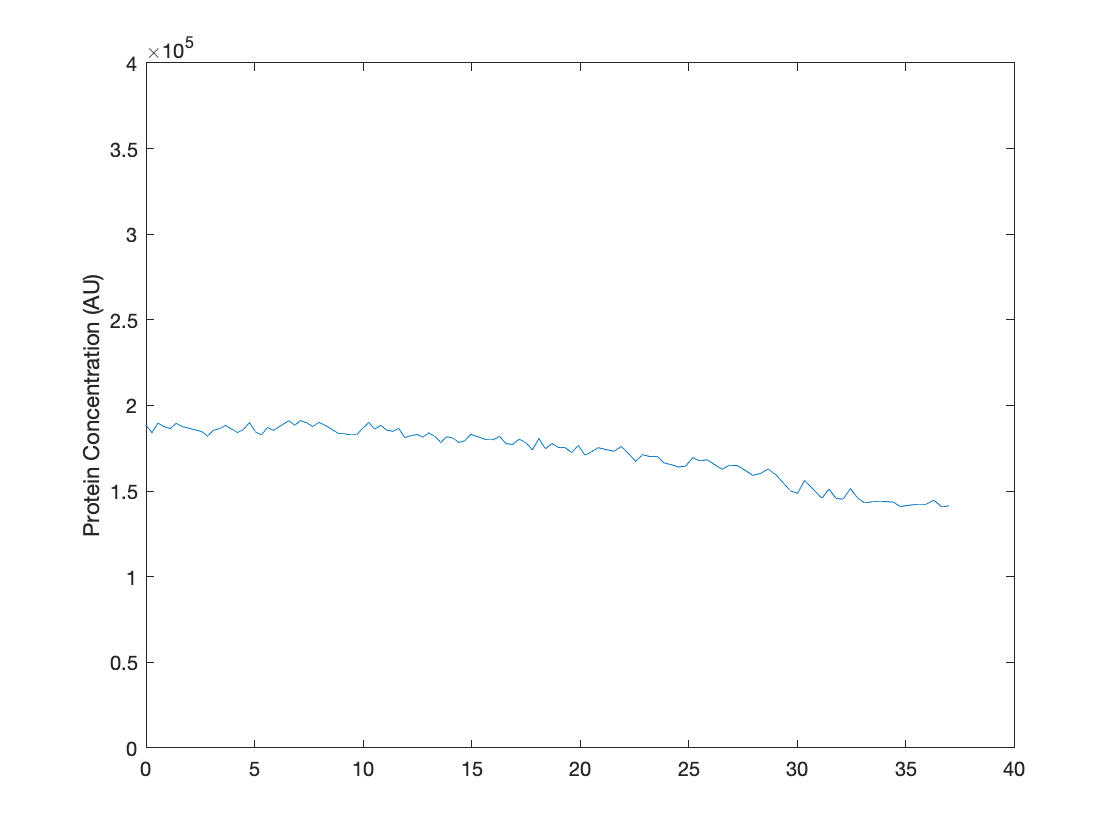

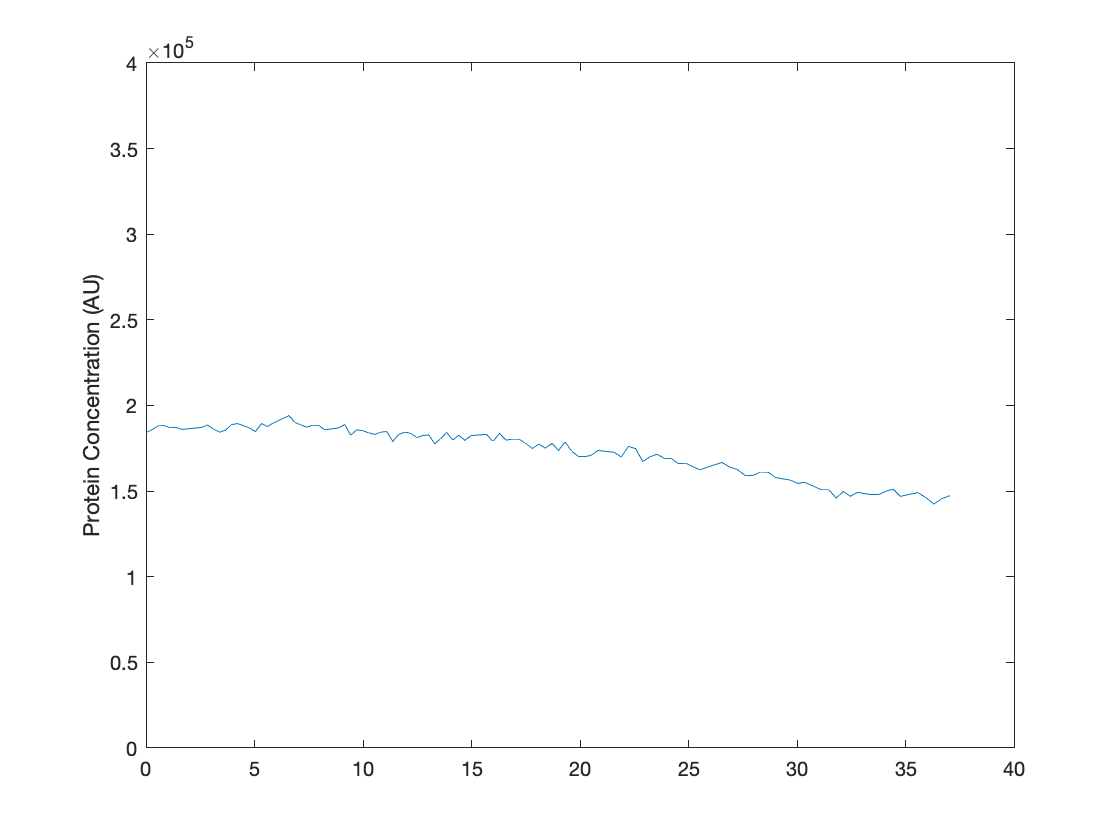

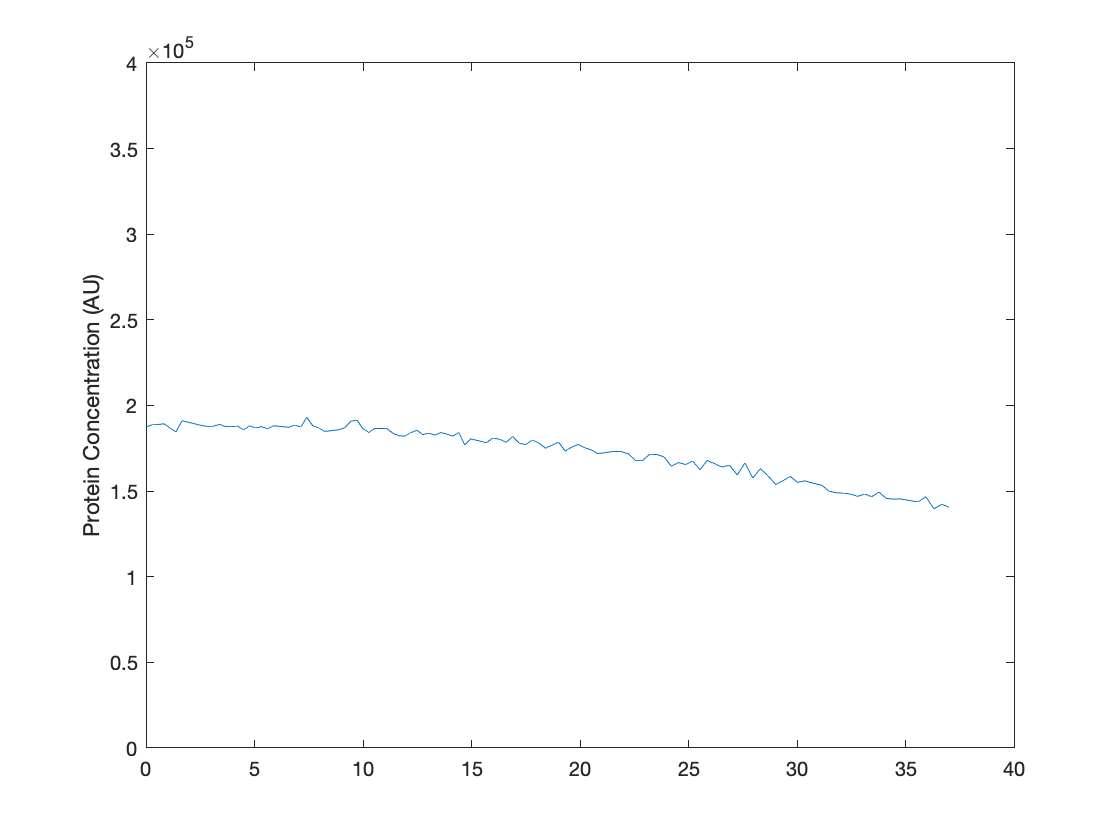

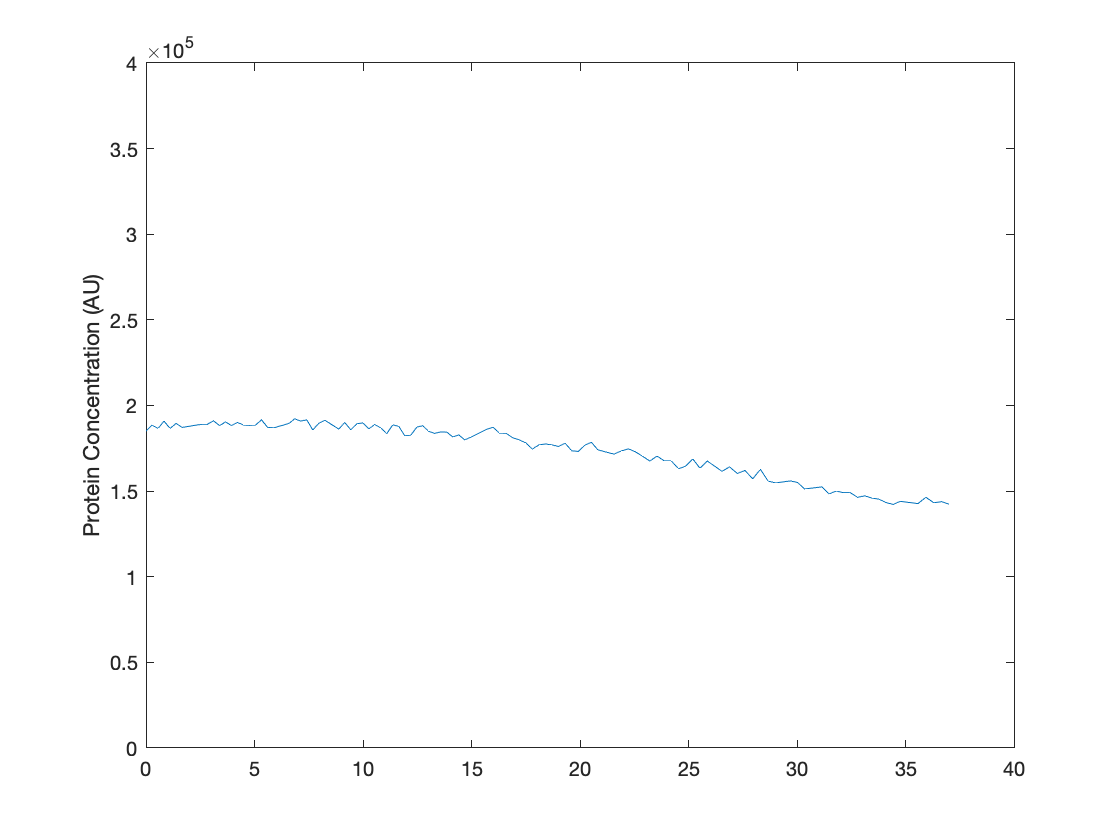

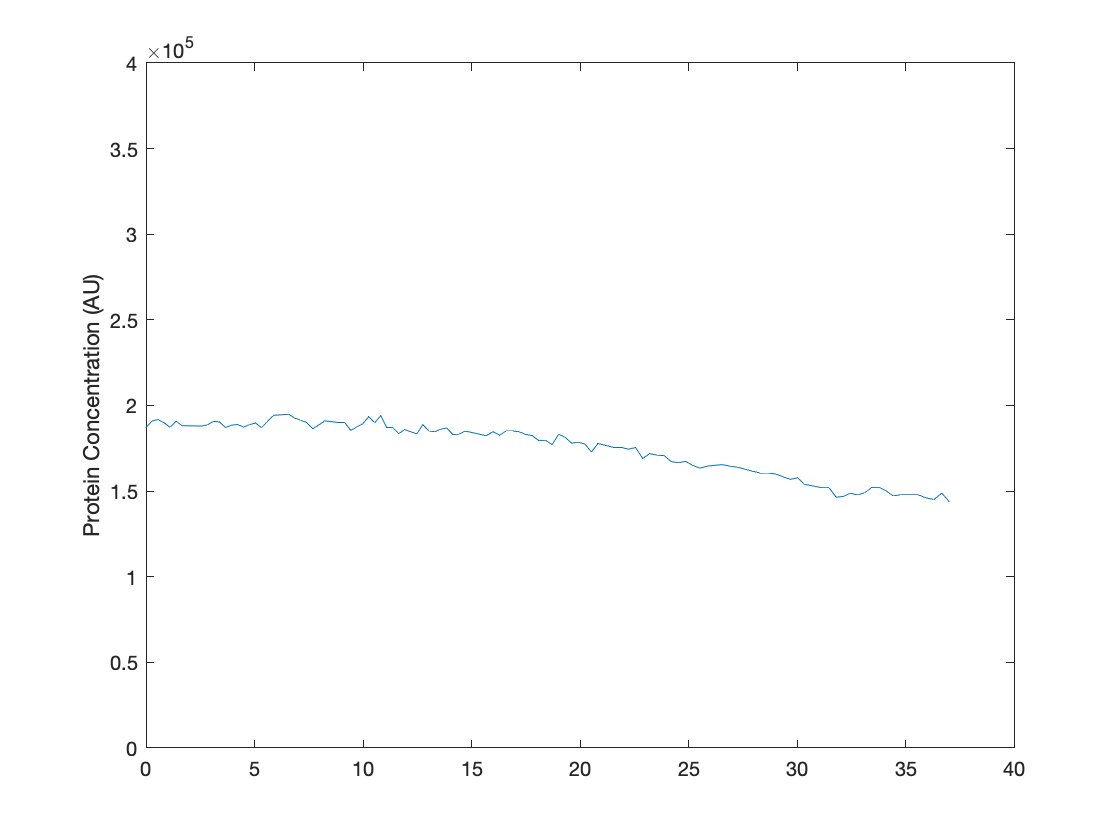

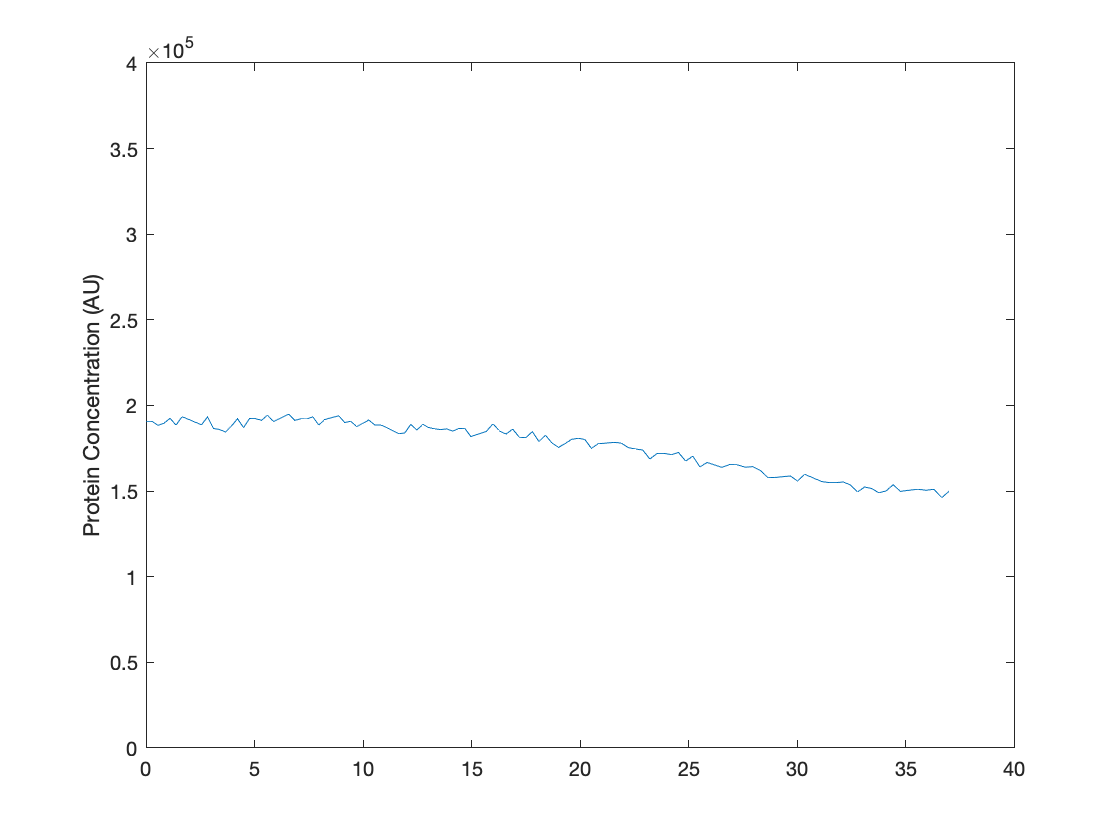

%for i = 39:47
for i = 25:58
    
    APbin_temp = i;
    protein_temp = data.nuclei.MeanVectorAP(start_frame:final_frame,APbin_temp);
    
    OverlayFig = figure;
    xlabel('Time (min)')
    title(['Mean Activity for x = ' num2str(APbinID(APbin_temp))])
    plot(Time, protein_temp);
    ylabel('Protein Concentration (AU)')
    ylim([0E5 4E5])
    
    saveas(OverlayFig,[FigPath '/mean_traces/bin_' num2str(i) '.pdf'])
end